# MATLAB Reproducibility Survey Analysis

**Dr David Wilby**, [Research Software Engineering Team, University of Sheffield](https://rse.shef.ac.uk)

version 1

As part of a fellowship from the [Software Sustainability Institute](https://software.ac.uk/) I'm gathering data around the opinions of researchers on topics in research reproducibility as they relate to MATLAB specifically.

The data will be used to help inform course materials for training researchers who use MATLAB to use the tools available in producing research output that is more reproducible.'

This MATLAB live script can be used to re-run the data analysis and present the results and is itself an example of *literate programming* - presenting the analysis and conclusions alongside one another. Clone its repository from GitHub or download the source code as a zip archive to run it locally.

Before we start, let's just do some setup.

% setup
clear %clear the workspace
filename = matlab.desktop.editor.getActiveFilename; % get name of this file
[dir,~,~] = fileparts(filename);
cd(fullfile(dir)); % move current folder to the root directory of the project
openProject("Survey.prj"); % open the project file

In the public version, we'll work with anonymised data from the survey, but privately, this live script was also used to randomly select one respondent for a GBP 50 gift card, you can see the process used at the bottom.

Firstly, we'll read in the data as a table and remove a few rows which have been manually identified as being spurious responses.

% Read in raw data file.
data_file = fullfile("data", "raw", "anonymised_responses.csv");
warning('OFF', 'MATLAB:table:ModifiedAndSavedVarnames')
rawData = readtable(data_file,...
    'VariableNamingRule','modify');

It's good research practice to include all the steps used in cleaning the data ready for analysis. Here, we'll also rename some columns to give them more concise names (since Google Forms, which was used in running the survey, uses the full text in the form to name columns, resulting in inconvenient names), for brevity, this is done in the custom function `renameColumns()`, which is available in the codebase.

% Remove spurious responses
cleanedData = rawData;
cleanedData([112, 113, 168, 174:179, 206], :) = [];

% Rename columns
cleanedData = renameColumns(cleanedData);


Lastly, we'll also tidy up the institution names, since this was a free text field in the form, this is a somewhat manual process as well, which I've achieved with code and included as part of the processing here.

% Make institution names uniform
cleanedData.institution = tidyInstitutions(cleanedData.institution);


Once that's done, we're ready to do some analysis. Most of these are done in custom functions which can be found in the `src` folder (short for "source code") of the repository.

## Who makes up the study group?

This survey was circulated via social media (e.g Twitter, Mastodon) and by a few mailing lists via research software engineers contacted through the RSE Society slack. At the University of Sheffield, where I work, it was also sent out to all users of MATLAB. These were chosen deliberately to target users in a university research setting. We can see from the raw data that the vast majority of respondents were based at academic research institutions, most of which were universities. There were no responses that needed to be removed as a result of being outside of this target group.

One caveat is that, without targeting more user groups consisting of all MATLAB users, many of the respondents may have been likely to be more expert than a representative sample by being on RSE mailing lists, following RSEs on social media etc. However, as you'll see, we collected self-perceived experience levels, allowing the data to be categorised on that basis.

To start with, I asked the respondents to indicate their self-perceived level of expertise with MATLAB, and with programming in general.

Let's divide this up according to their reported career stage, note that it was possible for respondents to select multiple career stages.

plotExperienceCharts(cleanedData)

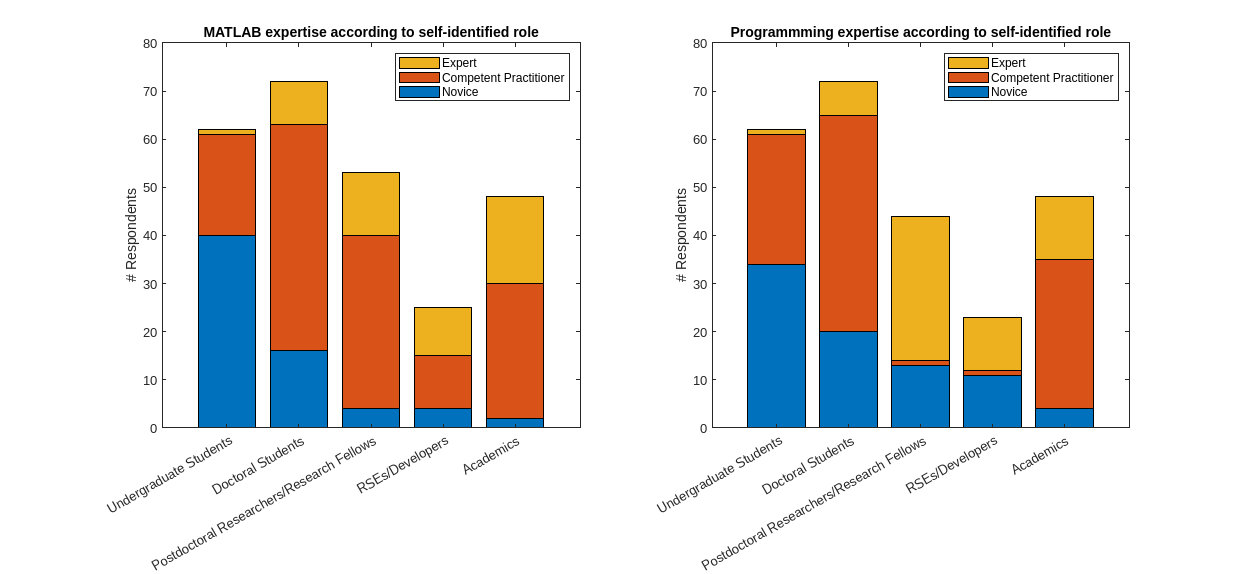

set(gcf,'Units','normalized','Position',[0 0 1 1.5]); 

As you might expect, we can conclude that undergraduate students were more likely to perceive themselves as novices and academics were more likely to report that thy were competent practitioners or experts both in MATLAB and in programming more generally. Whilst not so useful in itself, these data can be used later on for us to draw some conclusions about which experience levels are relevant to some other requirements.

## Awareness of and Use of Version Control

Now we can get into the questions that provide more insight that will be relevant to my training course.

Version control (or source code management) is an exceptionally valuable tool in any development of code. I wanted to know how likely our respondents were to use source code management tools such as **git** as well as online hosting and collaboration platforms such as **GitHub**. Additionally, I was interested to see whether there would be a difference in usage when it comes to working in MATLAB versus other languages.

For this and the next few questions, I asked participants to respond "Not aware of", "Aware of but don't use", "Aware of and use with MATLAB", "Aware of and use outside MATLAB", and they could choose more than one if they wanted to. In the analysis I've derived another classification "Use outside but not with MATLAB" which is what it sounds like.

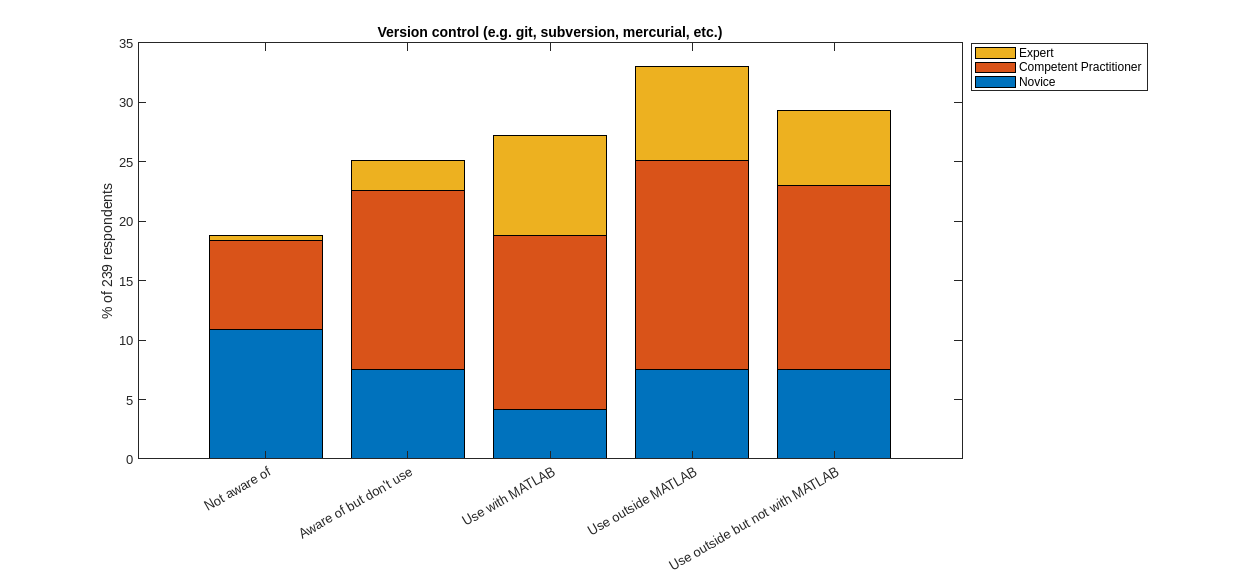

awarenessTable = cleanedData(:, {'role', 'matlabExperience', 'programmingExperience', 'awareness_versionControl', 'awareness_github', 'awareness_CICD', 'awareness_dataAvailability', 'awareness_dependencyMgmt', 'awareness_literateProgramming', 'awareness_docGen', 'awareness_softwareTesting'});

plotAwareness(awarenessTable, "awareness_versionControl")
title("Version control (e.g. git, subversion, mercurial, etc.)")

Without doing some statistical analysis, it is of course diffcult to draw precise conclusions, but let's treat the findings qualatively. (Note that if you want to do some stats here, you can contribute back to this repository via a pull request on GitHub).

For this question, I was pleasantly surprised to see that ~90% of respondents were aware of version control, higher than perhaps I might have expected, though our survey respondents may have been a slightly self-selected population. What's particularly interesting to me here is the ~25% who use version control outside of MATLAB, but not with it. Depending on whether participants interpreted the 'Use outside MATLAB' and 'Use outside but not with MATLAB' as being equivalent or not (that's a lesson for me on study design!), this could be seen to be as high as ~50%. Without digging further into why the "Aware of but don't use" group responded that way, we can't tell why, but we may be able to conclude that out of this group of 239 MATLAB users, up to around 75% don't use version control when working with MATLAB, despite most being aware of it.

Next, let's take a look at GitHub/GitLab/BitBucket.

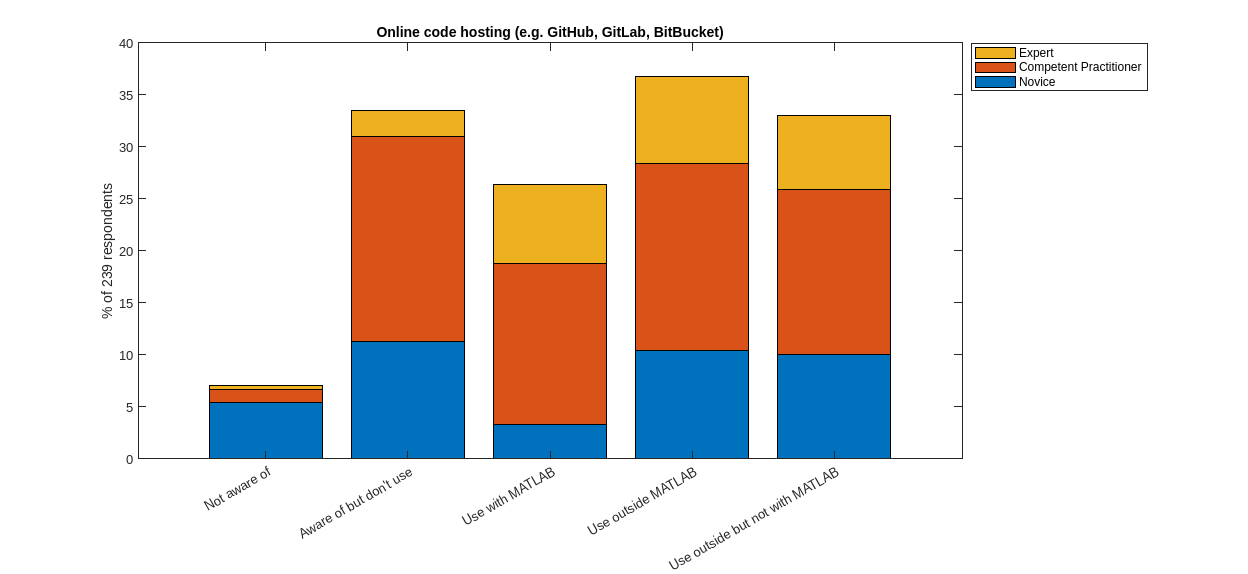

plotAwareness(awarenessTable, "awareness_github")
title("Online code hosting (e.g. GitHub, GitLab, BitBucket)")

Straight away, we can see that there's an increase in awareness in relation to the version control tools themselves, more participants are aware of GitHub than they are of git, which might be a lesson to those of us who support researchers.

Otherwise the pattern is broadly similar here, only 20% use GitHub when working with MATLAB.

### Dependency and Environment Management

When it comes to reproducibility, managing *dependencies* and *environment*  - i.e. the software that your code relies upon to run - is the fundamental challenge. It's not an easy thing to do, but once you do, it can allow you to run your code almost anywhere. In many ways this is the crux of reproducibility of research analysis.

For MATLAB, I found this a particularly difficult question to pose, and I'm not sure I've done the best job. Participants were asked to indicate their level of awareness and use of "Dependency and/or  environment management (e.g. conda, renv, etc.)" which gives the examples `conda` and `renv` - common environment management tools in python and R respectively. However, to my knowledge, MATLAB doesn't have equivalent tools. The closest is perhaps the "[Project](https://uk.mathworks.com/help/matlab/projects.html)", which we'll investigate further later on.

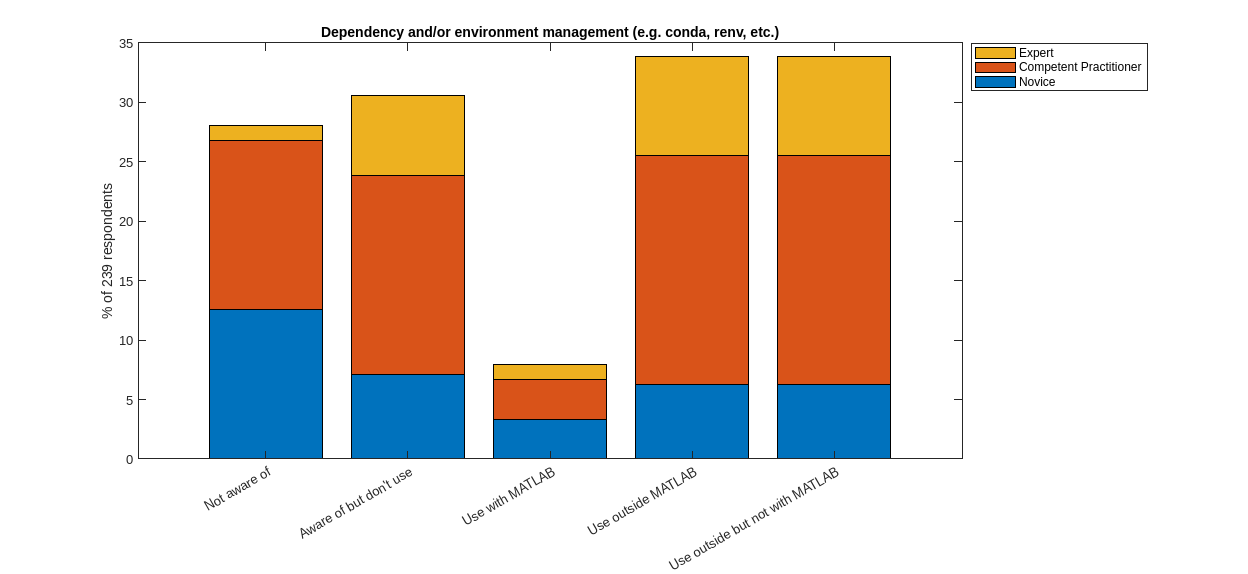

plotAwareness(awarenessTable, "awareness_dependencyMgmt")
title("Dependency and/or environment management (e.g. conda, renv, etc.)")

Here, it looks like most (if not all) of those participants who use these tools outside MATLAB, might not use them with MATLAB, but perhaps this is because conda and renv aren't relevant and participants were left to themselves to work out what dependency and environment managment looks like in MATLAB. However, some respondents do use these tools with MATLAB apparently, so I'm unsure what conclusion to draw here. Either way, it looks like a fairly small number use dependency or environment management with MATLAB, through lack of availability of tools or awareness of the concepts.

### Continuous Integration

Similarly, we asked participants to indicate their level of awareness and use of "Continuous Integration/Deployment (e.g. automated testing, GitHub Actions, Travis, Jenkins etc.)".

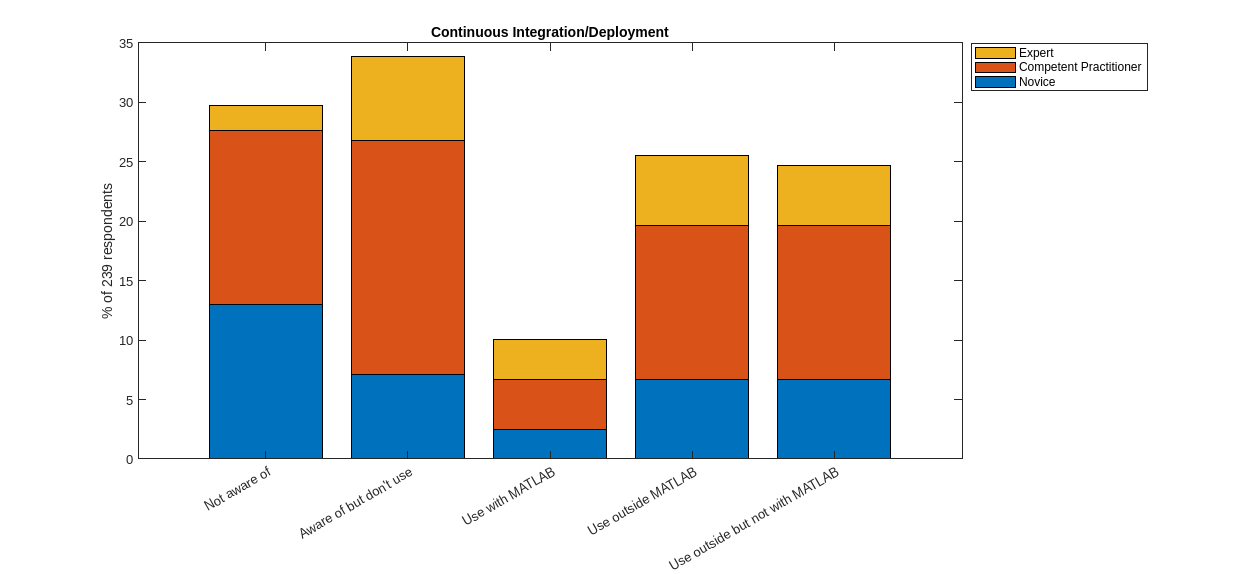

plotAwareness(awarenessTable, "awareness_CICD")
title("Continuous Integration/Deployment")

Perhaps predictably, awareness was lower for this slightly more advanced concept, but still fairly high at >80%. However, use of these tools with MATLAB was <10%, even with tools being available such as [GitHub actions for MATLAB](https://github.com/matlab-actions/overview).

### Literate Programming

An esoteric, but valuable, concept in research code, literate programming is something that MATLAB is fairly well tooled up for, look at this here livescript for proof! So I was interested to see what our participants had to say.

Once again for this set of questions, some test of comprehension of what was meant by "literate programming" might have been beneficial, but examples were given as "Literate programming (e.g. jupyter notebooks, rmarkdown, live scripts, quarto)".

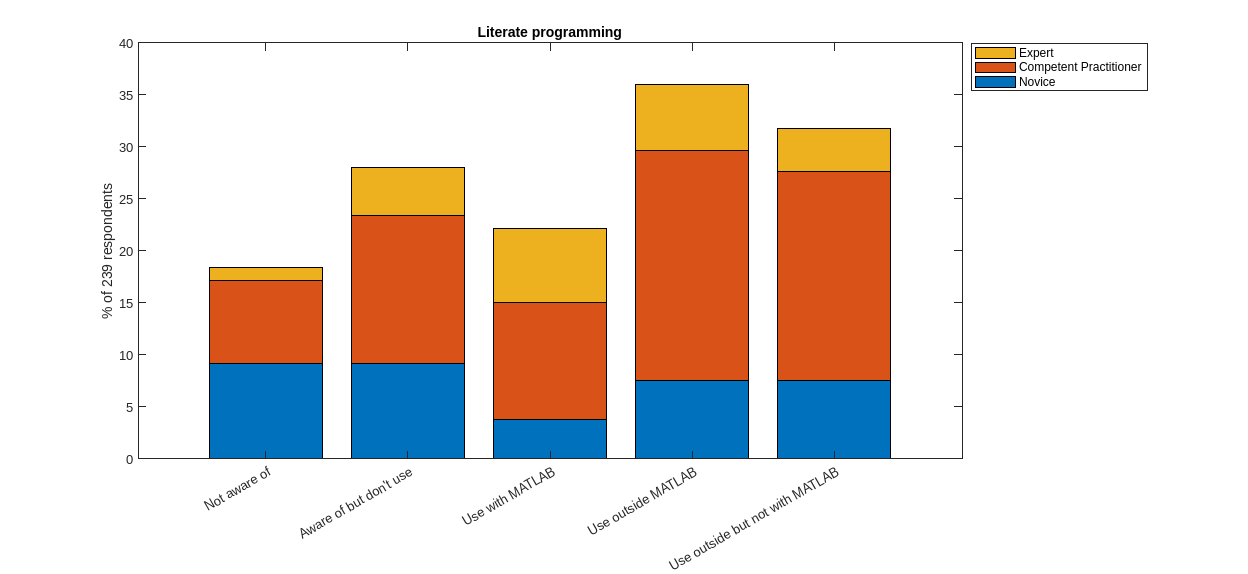

plotAwareness(awarenessTable, "awareness_literateProgramming")
title("Literate programming")

Understandably, we see greater usage in MATLAB, though still not as many respondents who are aware but don't use the tools, or use them outside of MATLAB exclusively.

### Software Testing

Similarly to some of the above concepts, software testing is a valuable tool in improving code reliability, though not *strictly essential*  for reproducibility. Personally I think that the test framework and tools available in MATLAB are excellent, so I was interested to see what the survey had to say.

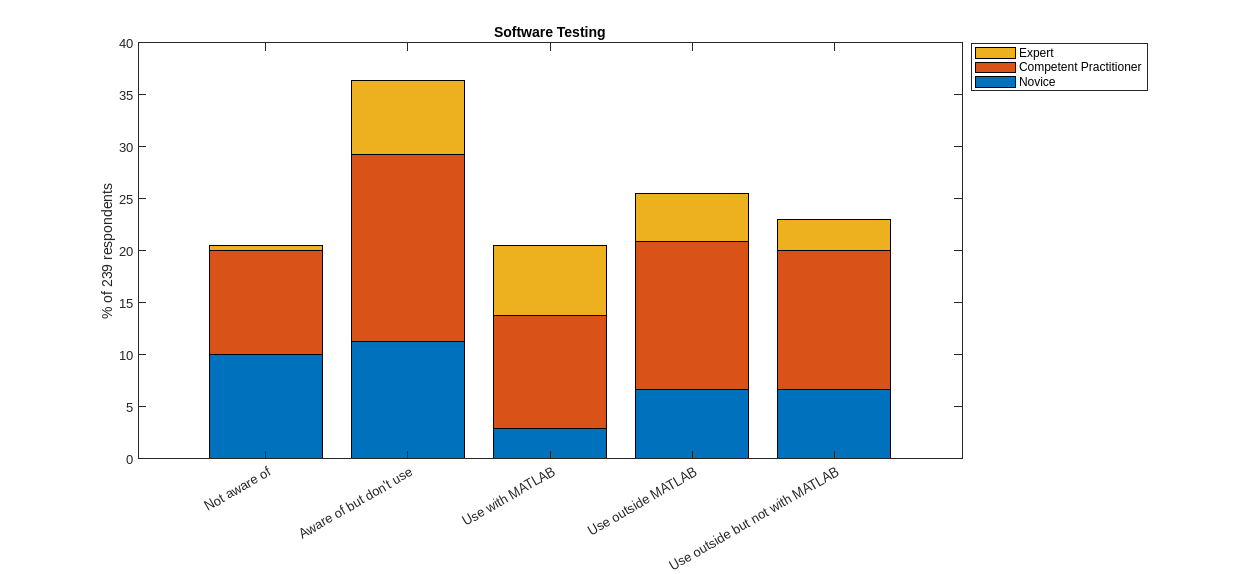

plotAwareness(awarenessTable, "awareness_softwareTesting")
title("Software Testing")

Here we see a big group of participants who are aware of testing but don't use it, but also a large number who do use it in MATLAB. Still there are many who use testing outiside of MATLAB but not inside.

## Usage of Git with MATLAB

Next up, I was interested to know how about how researchers who use git choose to interact with it. There are many interfaces available for git, including tools built into the MATLAB IDE itself.

The question *verbatim* was "**Do you use **[**git**](https://git-scm.com/)** as a version control system with MATLAB? If so, which interface(s) do you use?"**

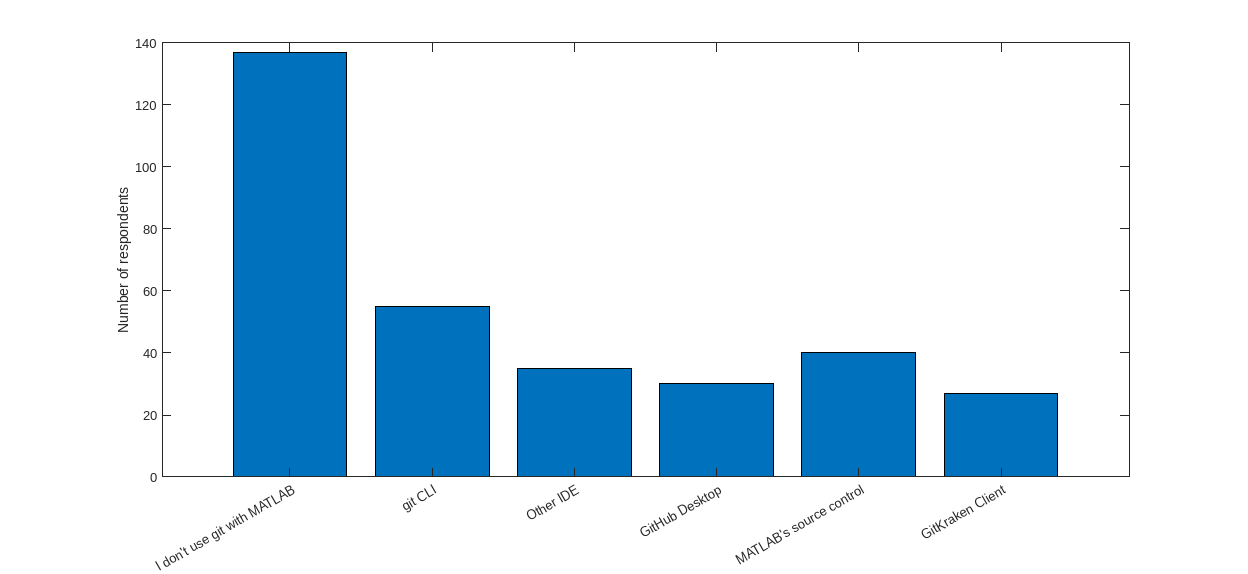

gitTable = cleanedData(:, {'role', 'matlabExperience', 'programmingExperience', 'gitUsage'});

barVals = [height(gitTable(contains(gitTable.gitUsage, "I don't use git with MATLAB"), :)) ...
    height(gitTable(contains(gitTable.gitUsage, "git's command line interface") & ~contains(gitTable.gitUsage, "I don't use git with MATLAB"), :)) ...
    height(gitTable(contains(gitTable.gitUsage, "Other development environment git interface (e.g. VScode, Rstudio, PyCharm)") & ~contains(gitTable.gitUsage, "I don't use git with MATLAB"), :)) ...
    height(gitTable(contains(gitTable.gitUsage, "GitHub Desktop") & ~contains(gitTable.gitUsage, "I don't use git with MATLAB"), :)) ...
    height(gitTable(contains(gitTable.gitUsage, "MATLAB's source control tools") & ~contains(gitTable.gitUsage, "I don't use git with MATLAB"), :)) ...
    height(gitTable(contains(gitTable.gitUsage, "GitKraken Client") & ~contains(gitTable.gitUsage, "I don't use git with MATLAB"), :)) ...
    ];

labels = {'I don''t use git with MATLAB', 'git CLI', 'Other IDE', 'GitHub Desktop','MATLAB''s source control', 'GitKraken Client'};
x = categorical(labels);
x = reordercats(x,labels);
bar(x, barVals);
ylabel('Number of respondents')

Immediately we can see that the biggest group here are those who choose not to use git with MATLAB at all. I haven't analysed how many of this group don't use git at all, though you *could* contribute that analysis via a pull request :D

Out of those who use git when working with MATLAB there's a fairly even spread across the interfaces mentioned including the native git command line interface, tools in *other* IDEs such as VScode or pycharm, GUIs such as GitHub Desktop or GitKraken client, and a fairly good chunk of users who do use the tools built into MATLAB itself. It's worth pointing out here that the git integration in the GUI seems to have some nice impovements in the new MATLAB IDE launched recently in R2023a.

## Usage of MATLAB Tools and Features

Next up, participants were asked to indicate which of a list of MATLAB features relating to reproducibility and code quality that they use.

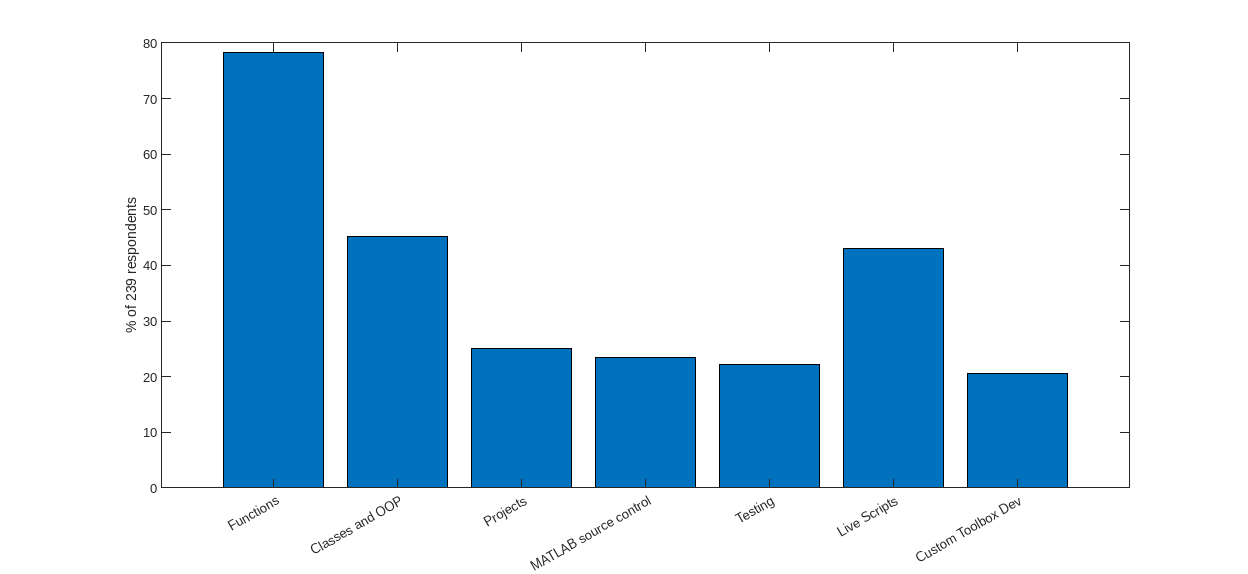

matlabToolsTable = cleanedData(:, {'role', 'matlabExperience', 'programmingExperience', 'matlabFeatures'});

barVals = 100*[height(matlabToolsTable(contains(matlabToolsTable.matlabFeatures, "Functions"), :)) ...
    height(matlabToolsTable(contains(matlabToolsTable.matlabFeatures, "Classes and Object-Oriented Programming"), :)) ...
    height(matlabToolsTable(contains(matlabToolsTable.matlabFeatures, "Projects"), :)) ...
    height(matlabToolsTable(contains(matlabToolsTable.matlabFeatures, "MATLAB's source control integration"), :)) ...
    height(matlabToolsTable(contains(matlabToolsTable.matlabFeatures, "Testing"), :)) ...
    height(matlabToolsTable(contains(matlabToolsTable.matlabFeatures, "Live Scripts"), :)) ...
    height(matlabToolsTable(contains(matlabToolsTable.matlabFeatures, "Custom toolbox development"), :)) ...
    ]/height(matlabToolsTable);

labels = {'Functions', 'Classes and OOP', 'Projects', 'MATLAB source control', 'Testing', 'Live Scripts', 'Custom Toolbox Dev'};
x = categorical(labels);
x = reordercats(x,labels);

bar(x, barVals)

ylabel(strcat("% of ", num2str(height(matlabToolsTable)), " respondents"))

Out of the list, language features such as functions and classes were the most popular, but live scripts also see a high level of usage here as well, which is great. The other tools such as projects, source control, testing and custom toolbox development, see less use by this group, but still a fairly high proportion at around 20%.

## Demand for training

Importantly, I wanted to find out what the relative demand for learning some of these concepts and tools might be, as well as the training formats preferred.

Across the topics asked about (Projects, testing, live scripts, version control, toolbox development, publication and licensing) there was a consistent demand for training of around 25-30% of participants indicating some kind of demand. The preference for structured training versus self-guided learning varied between topics, with some of the perhaps more *difficult* topics leaning more strongly towards structured training, though there was a substantial demand for both for every topic. This is something I was keen to know about with regards to whether when developing materials one should consider the different demands of these two formats.

There aren't any particularly stark findings here, the message seems to be that there's a mixed bag of attitudes towards demand for training in these areas with no striking spikes or absences.

Interestingly though, when it comes to software licensing, in comparison to the other topics asked about here, there was a rise in lack of interest for training, but a drop in those participants who were already familiar with the topic. When it comes to reproducibility and open research, licensing is what legally allows other people to use your code, so whilst the participants indicated a lack of demand for training here, I might suggest that this result indicates a greater need for it.

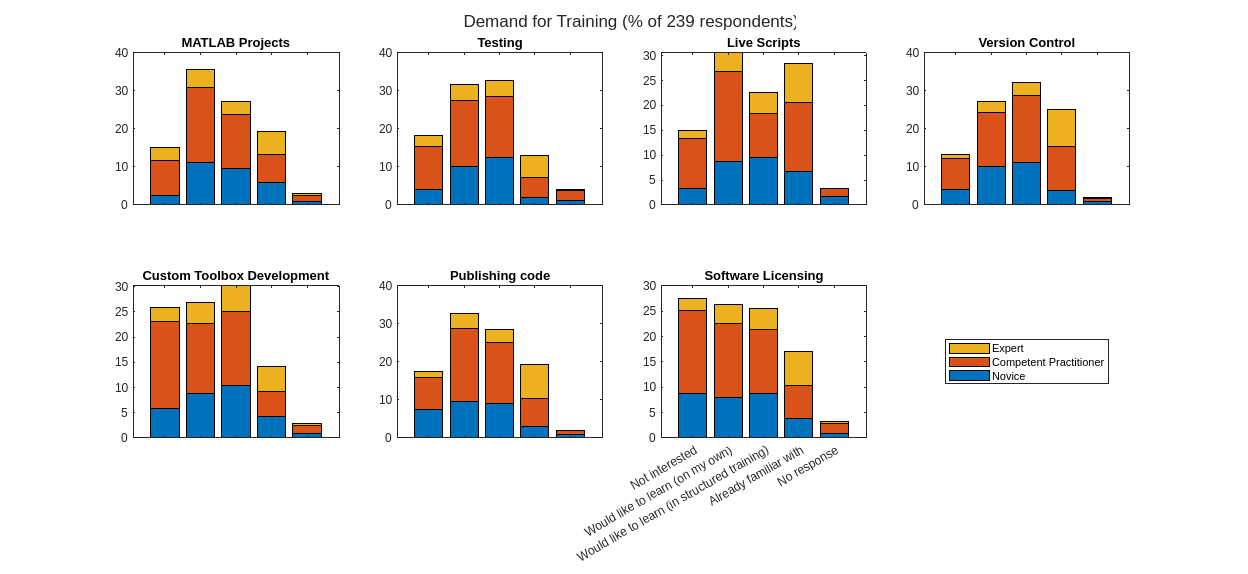

t=tiledlayout("flow");
title(t, strcat("Demand for Training (% of 239 respondents)"))
nexttile
h = plotTrainingDemand(cleanedData, "trainingDemand_projects");
title("MATLAB Projects")
nexttile
plotTrainingDemand(cleanedData, "trainingDemand_testing");
title("Testing")
nexttile
plotTrainingDemand(cleanedData, "trainingDemand_livescripts");
title("Live Scripts")
nexttile
plotTrainingDemand(cleanedData, "trainingDemand_versioncontrol");
title("Version Control")
nexttile
plotTrainingDemand(cleanedData, "trainingDemand_customtoolboxes");
title("Custom Toolbox Development")
nexttile
plotTrainingDemand(cleanedData, "trainingDemand_publishingcode");
title("Publishing code")
nexttile
plotTrainingDemand(cleanedData, "trainingDemand_licensing", true);
title("Software Licensing")
stackedBarLabels = {'Novice', 'Competent Practitioner', 'Expert'};
l = legend(flip(h), flip(stackedBarLabels), "Location","northeast");
l.Layout.Tile = 8;

## General Preferences on Training and Guidance

Finally, we looked into the preferences of the participants in general when it comes to training, including the formats of training and where they turn to for guidance.

As you might predict, people like all sorts of different training formats, even blogs and in-person lectures, which were the least popular, though still with a substantial share each.

I think that this shows that offering training in a variety of formats, and perhaps *designing* training to be suitable for them, might  enhance the utility of the materials and help more researchers to get more out of them.

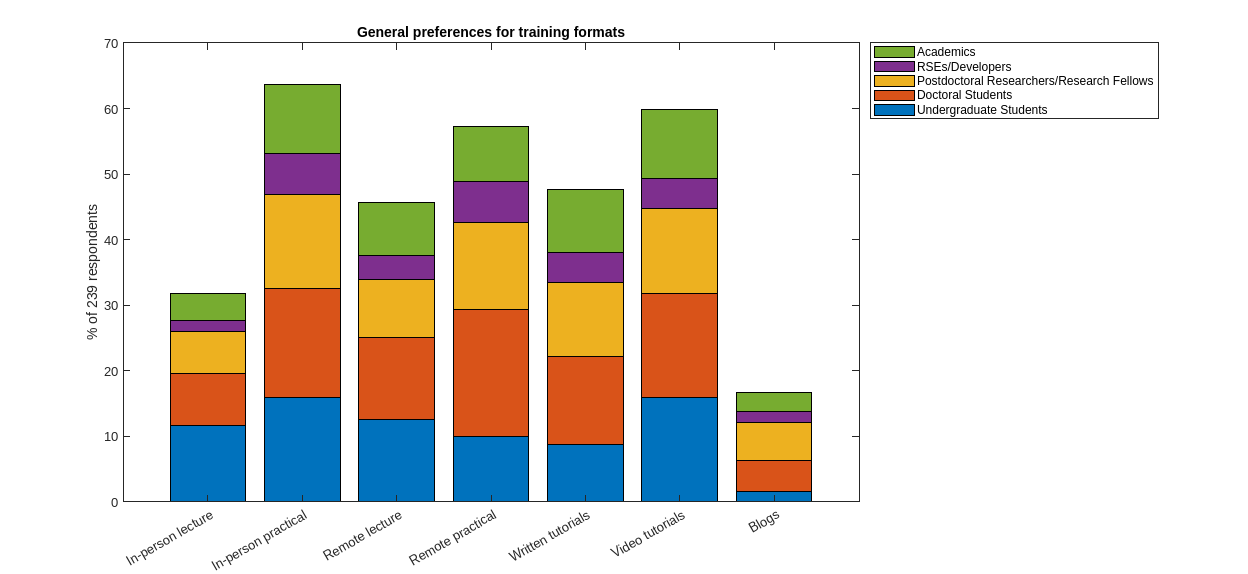

plotTrainingPreferences(cleanedData)
title('General preferences for training formats')

When it comes to seeking guidance it looks like our respondents are using a mixture of online sources as well as colleagues, but that support through their institutions are either not being used, or aren't available.

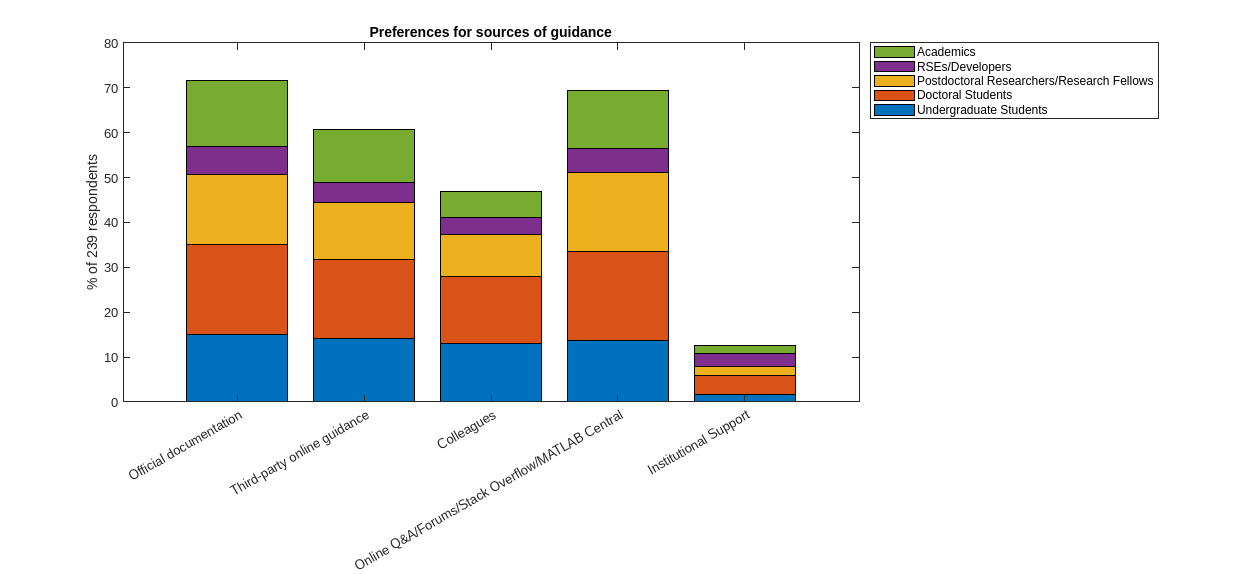

plotGuidancePreferences(cleanedData)
title('Preferences for sources of guidance')

### And Finally...

Time to randomly select a respondent to receive the prize. (Although not if this is the public version!)

if ~ismember("EmailAddress", cleanedData.Properties.VariableNames)
    disp('No EmailAddress column in data. Do you have the deanonymised responses?');
else
    winner = "";
    while strcmp(winner, "")
        winner  = cleanedData.EmailAddress(randi(size(cleanedData, 1)));
    end
    
    fprintf('And the winner is %s !\n', string(winner));
end

No EmailAddress column in data. Do you have the deanonymised responses?
